% Clear workspace, command window, and close all figures
clc;
clear all;
close all;


% Specify the filename and extract text data
filename = "MushokuTensseiChp1Vol1.txt";
textdata = extractFileText(filename);

% Part b: Text data preprocessing
document = tokenizedDocument(textdata);
rawbag = bagOfWords(document);

% Enhance document with part-of-speech details, remove stop words,
% normalize words using lemmatization, erase punctuation,
% remove short words (length less than 2), and remove long words (length greater than 15)
document = addPartOfSpeechDetails(document);
document = removeStopWords(document);
document = normalizeWords(document, "Style", "lemma");
document = erasePunctuation(document);
document = removeShortWords(document, 2);
document = removeLongWords(document, 15);
afterbag = bagOfWords(document);

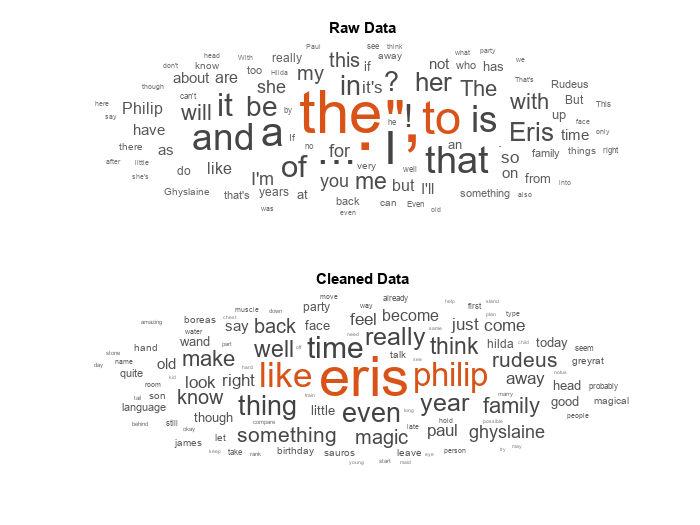


% Part c: Visualize word clouds for raw and cleaned data
figure;
nexttile;
wordcloud(rawbag);
title("Raw Data");

nexttile;
wordcloud(afterbag);
title("Cleaned Data");

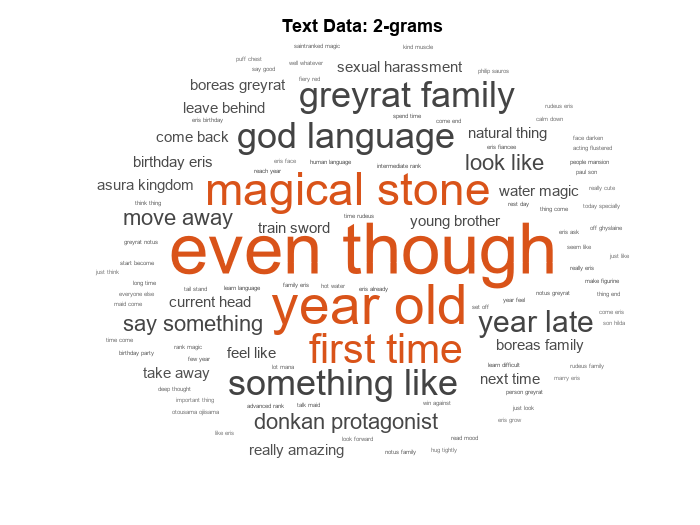


% Create bag of 2-grams and visualize word cloud
bag2grams = bagOfNgrams(document, 'NgramLengths', 2);
figure;
nexttile;
wordcloud(bag2grams);
title("Text Data: 2-grams");

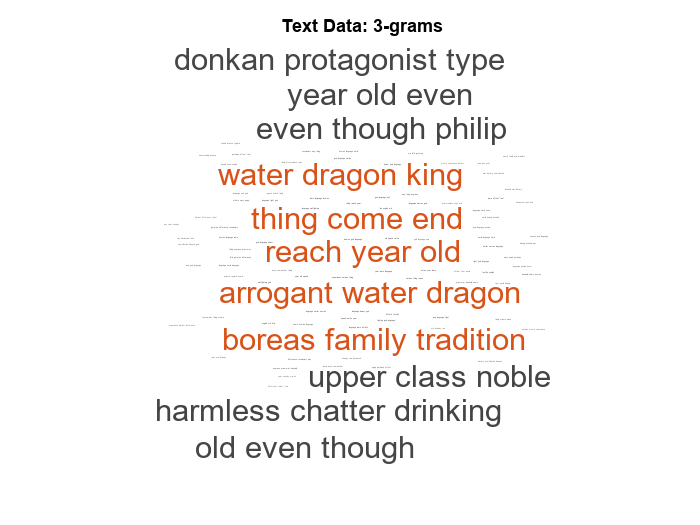


% Create bag of 3-grams and visualize word cloud
bag3grams = bagOfNgrams(document, 'NgramLengths', 3);
figure;
nexttile;
wordcloud(bag3grams);
title("Text Data: 3-grams");


% Part d: Preprocess data for Neural Network
Startoftextchar = compose("\x0002");
Whitespacechar = compose("\x0007");
Endoftextchar = compose("\x2403");
Newlinechar = compose("\x0086");

% Add start-of-text character and replace space and newline characters
textdata = Startoftextchar + textdata;
textdata = replace(textdata, [" " newline], [Whitespacechar Newlinechar]);

% Obtain unique characters and their count
uniquechar = unique([textdata{:}]);
numuniquechar = numel(uniquechar);
numdocument = numel(textdata);

% Initialize cell arrays for input and output data
Xtrain = cell(1, numdocument);
Ytrain = cell(1, numdocument);

% Loop through each document to create input-output pairs
for i = 1:numel(textdata)
    characters = textdata{i};
    sequencelen = numel(characters);
    
    % Create binary input matrix X using one-hot encoding
    [~, idx] = ismember(characters, uniquechar);
    X = zeros(numuniquechar, sequencelen);
    
    for j = 1:sequencelen
        X(idx(j), j) = 1;
    end
    
    % Create categorical output Y by shifting characters
    charactershifted = [cellstr(characters(2:end)')' Endoftextchar];
    Y = categorical(charactershifted);
    
    % Store input and output pairs in cell arrays
    Xtrain{i} = X;
    Ytrain{i} = Y;
end